% -------------------------------------------------------------------------
% 1. 데이터 불러오기
% -------------------------------------------------------------------------
clear; close all; clc;

% *** 사용자 설정: Excel 파일 이름을 실제 파일명으로 변경하세요. ***
file_path = 'Encoder.Data.xlsx'; 

try
    data_all = readmatrix(file_path);
    % 데이터가 정상적으로 로드되었는지 확인
    if size(data_all, 2) < 2
        error('데이터 파일은 최소 2개의 열을 포함해야 합니다.');
    end
catch ME
    disp('*** 오류: Excel 파일을 불러올 수 없습니다. 파일 경로와 이름을 확인하세요. ***');
    rethrow(ME);
end

% -------------------------------------------------------------------------
% 2. 데이터 분리 (X, Y 축 정보 교체)
% -------------------------------------------------------------------------
% 사용자의 요청대로 X축과 Y축의 정보를 서로 바꿉니다.

% 기존: X=각도(1열), Y=인코더(2열)
% 변경: X=인코더(2열), Y=각도(1열)

% X축 데이터: 인코더 값 (Encoder Value) - 2번째 열 사용
x_encoder = data_all(:, 2); 

% Y축 데이터: 각도 (Angle) - 1번째 열 사용
y_angle = data_all(:, 1);

% -------------------------------------------------------------------------
% 3. 그래프 플롯 및 선형 회귀
% -------------------------------------------------------------------------

figure;

disp(' ');

disp('---------------------------------------------------------');

---------------------------------------------------------


disp(['총 ' num2str(length(x_encoder)) '개의 데이터 포인트가 플롯되었습니다.']);

총 234개의 데이터 포인트가 플롯되었습니다.


disp('---------------------------------------------------------');

---------------------------------------------------------


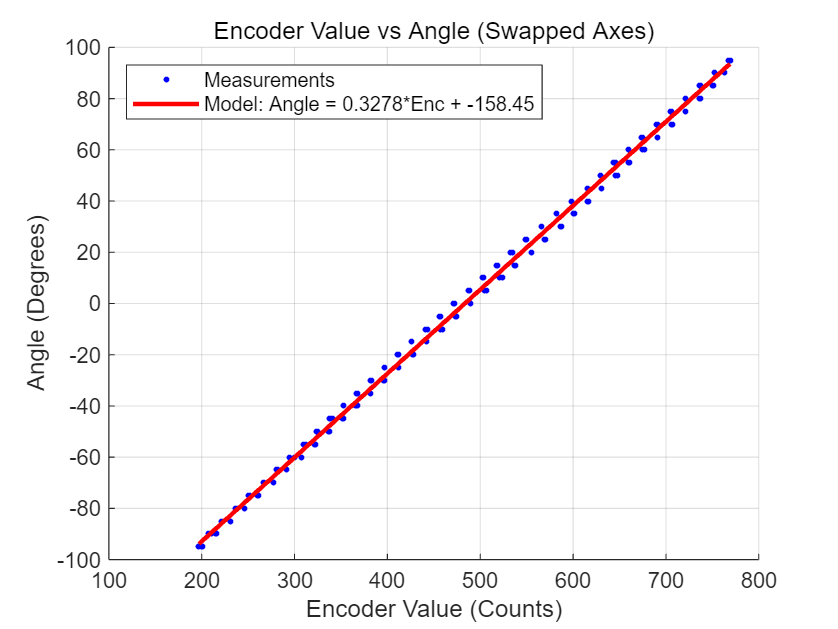


% 선형 회귀 (Linear Regression)
% 이제 모델은: Angle = m * Encoder + b 형태가 됩니다.
P = polyfit(x_encoder, y_angle, 1); 
m = P(1); % 기울기 (Degree per Count)
b = P(2); % y절편 (Offset)
y_linear_fit = polyval(P, x_encoder);

hold on;

% 1. 산점도 (Scatter Plot) - 측정 데이터
plot(x_encoder, y_angle, 'b.', 'MarkerSize', 8, 'DisplayName', 'Measurements');

% 2. 선형화 모델 (Linearization Model) - 추세선
plot(x_encoder, y_linear_fit, 'r-', 'LineWidth', 2, ...
    'DisplayName', sprintf('Model: Angle = %.4f*Enc + %.2f', m, b)); 

% 그래프 꾸미기
title('Encoder Value vs Angle (Swapped Axes)');
xlabel('Encoder Value (Counts)'); % X축이 이제 인코더 값입니다.
ylabel('Angle (Degrees)');        % Y축이 이제 각도입니다.
grid on;
legend('show', 'Location', 'NorthWest');
hold off;


% 통계적 피팅 결과 출력 (R-squared 등 확인용)
disp('선형 모델 상세 정보:');

선형 모델 상세 정보:


mdl = fitlm(x_encoder, y_angle)

mdl = 선형 회귀 모델:
    y ~ 1 + x1

추정된 계수:
                   Estimate        SE         tStat       pValue   
                   ________    __________    _______    ___________

    (Intercept)    -158.45        0.50601    -313.13    9.7494e-307
    x1             0.32776     0.00098649     332.25    1.0706e-312


관측값 개수: 234, 오차 자유도: 232
RMS 오차: 2.59
결정계수: 0.998, 수정된 결정계수: 0.998
상수 모델에 대한 F-통계량: 1.1e+05, p-값 = 1.07e-312